clear all
load('entradaSquare.mat')
load('salidaSquare.mat')

entradaEntrenamiento = entradaSquare(1:1500)

entradaEntrenamiento =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


salidaEntrenamiento = salidaSquare(1:1500)

salidaEntrenamiento =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


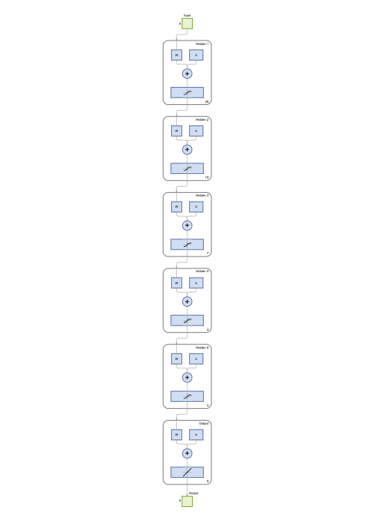


red = fitnet([20,10,7,4,3]);
view(red)

red.layers{1}.transferFcn='poslin'

red =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 6
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 354
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1; 1; 1]
      

red.layers{2}.transferFcn='poslin'

red =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 6
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 354
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1; 1; 1]
      

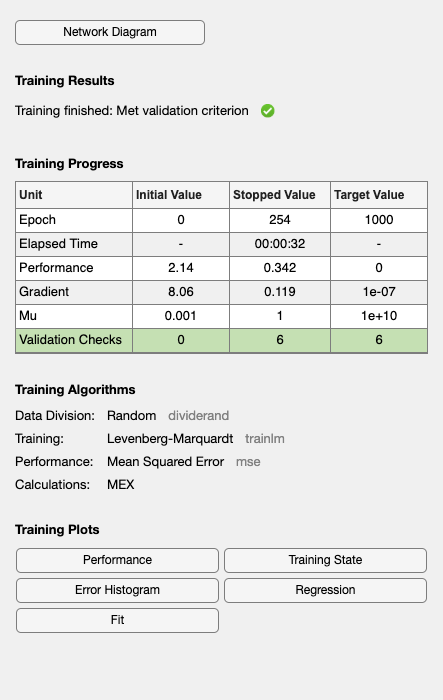

red =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 6
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 378
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1; 1; 1]
      

tr = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [4 5 6 7 9 10 11 13 14 15 17 18 21 22 23 24 25 27 28 29 33 35 36 37 40 41 44 45 47 48 49 50 51 52 54 55 59 60 63 64 66 67 69 70 71 73 74 75 77 80 81 82 84 86 87 88 89 91 93 95 96 97 100 101 102 104 107 109 110 111 112 113 114 115 … ]
          valInd: [3 12 16 20 26 30 34 39 42 53 61 62 72 78 85 90 92 99 108 131 133 140 145 150 152 161 166 168 171 180 186 188 189 194 206 214 218 219 226 241 246 248 250 258 262 271 276 278 282 287 291 295 306 317 318 323 332 335 337 362 374 377 … ]
         testInd: [1 2 8 19 31 32 38 43 46 56 57 58 65 68 76 79 83 94 98 103 105 106 167 170 174 179 182 183 191 205 208 212 213 251 257 260 264 269 275 280 281 286 293 298 305 316 331 342 343 353 360 363 373 379 389 391 403 413 414 42

[red,tr] = train(red,entradaEntrenamiento.',salidaEntrenamiento.')